% Parámetros del sistema
R_th_CPU = 0.5;        % Resistencia térmica del CPU (K/W)
C_th_CPU = 100;        % Capacidad térmica del CPU (J/K)
R_th_dis = 1.0;        % Resistencia térmica del disipador (K/W)
C_th_dis = 200;        % Capacidad térmica del disipador (J/K)

% Coeficientes del denominador (segundo orden)
a2 = C_th_CPU * C_th_dis * (R_th_CPU + R_th_dis);
a1 = C_th_CPU * R_th_CPU + C_th_dis * R_th_dis;
a0 = 1;

% Coeficientes del numerador para cada entrada
num_Tamb = [1];                   % Numerador para T_amb
num_Pcarga = [R_th_CPU];          % Numerador para P_carga

% Denominador común
den = [a2, a1, a0];

% Crear funciones de transferencia
G_Tamb = tf(num_Tamb, den)       % FT para T_amb -> T_CPU

G_Tamb =
 
            1
  ---------------------
  30000 s^2 + 250 s + 1
 
Continuous-time transfer function.



G_Pcarga = tf(num_Pcarga, den)   % FT para P_carga -> T_CPU

G_Pcarga =
 
           0.5
  ---------------------
  30000 s^2 + 250 s + 1
 
Continuous-time transfer function.



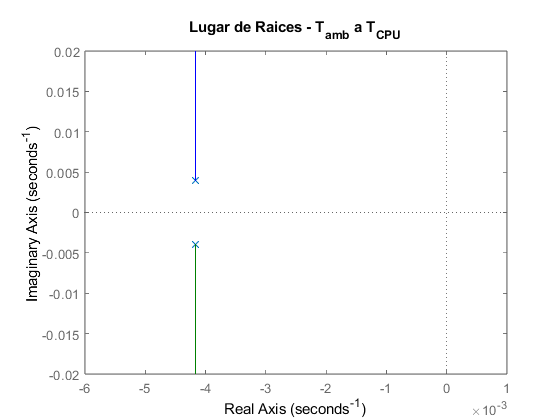



% Análisis de lugar de raíces
figure;
rlocus(G_Tamb);
title('Lugar de Raices - T_{amb} a T_{CPU}');

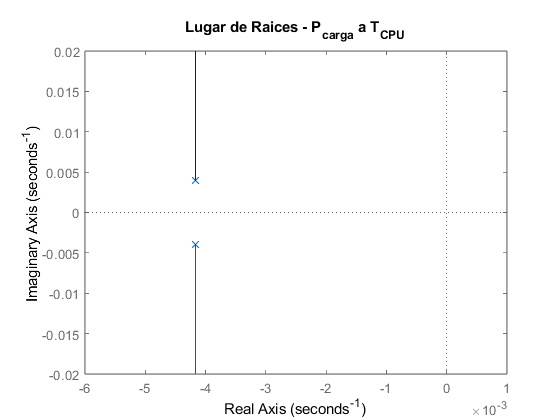


figure;
rlocus(G_Pcarga);
title('Lugar de Raices - P_{carga} a T_{CPU}');

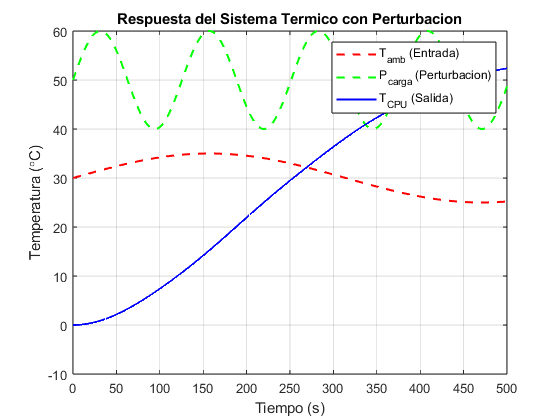


% Simulación del sistema con perturbación
t = 0:0.1:500;                    % Tiempo (s)
T_amb = 30 + 5*sin(0.01*t);       % Temperatura ambiente oscilante
P_carga = 50 + 10*sin(0.05*t);    % Potencia de carga oscilante

% Simulación de la respuesta
T_CPU_Tamb = lsim(G_Tamb, T_amb, t);  % Respuesta a T_amb
T_CPU_Pcarga = lsim(G_Pcarga, P_carga, t); % Respuesta a P_carga

% Respuesta total (superposición)
T_CPU = T_CPU_Tamb + T_CPU_Pcarga;

% Graficar resultados
figure;
plot(t, T_amb, 'r--', 'LineWidth', 1.5); hold on;
plot(t, P_carga, 'g--', 'LineWidth', 1.5);
plot(t, T_CPU, 'b-', 'LineWidth', 1.5);
grid on;
xlabel('Tiempo (s)');
ylabel('Temperatura (\circC)');
legend('T_{amb} (Entrada)', 'P_{carga} (Perturbacion)', 'T_{CPU} (Salida)');
title('Respuesta del Sistema Termico con Perturbacion');